clear; clc;
qtdCols = 5;                        %Define quantas colunas irei utilizar levando em consedaração o arquivo importado%

#### Importando os dados para o programa

data = readmatrix('C:\Users\gabri\OneDrive\Área de Trabalho\scholl\AI\data-analisys\tables/final.csv');
sizes = size(data);

#### Definindo dados de atuação (de acordo com a tabela recebida)

x = data(:, 1:sizes(2)-1);                %Rows and columns (definindo variaveis de entrada)%
y = data(:,sizes(2));                     %Rows and Columns (definindo variavel de previsão)%
m = length(y);                            %Pega a quantidade de dados que temos para resultados%

#### Data preparing

mistura os dados de cada class

xs = x(1,:);
ys = y(1,:);
for i = 1:1:sizes(1)
    rd = randsample(sizes(1),1);
    
    xs = x(i,:);
    ys = y(i,:);

    x(i, :) = x(rd,:);
    x(rd,:) = xs;
    
    y(i, :) = y(rd,:);
    y(rd,:) = ys;
end

#### Data separate

separa o conjunto de treino do conjunto de testes

testPr = 0.3;
trainsPr = round(sizes(1)*(1-testPr));

Xtrain = x(1:trainsPr,:);
Ytrain = y(1:trainsPr,:);

Xtest = x(trainsPr + 1 : sizes(1), :);
Ytest = y(trainsPr + 1 : sizes(1), :);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.20613 |      1.8684 |     0.20613 |     0.20613 |     0.013487 |     0.053631 |


|    2 | Accept |     0.20613 |     0.58763 |     0.20613 |     0.20613 |    0.0019185 |       786.86 |


|    3 | Best   |    0.064623 |     0.47367 |    0.064623 |    0.064637 |       1.7508 |       42.856 |


|    4 | Accept |     0.19528 |      2.0677 |    0.064623 |     0.07588 |        21.79 |     0.027708 |


|    5 | Accept |    0.066509 |     0.34508 |    0.064623 |    0.064766 |       1.3844 |       40.222 |


|    6 | Best   |    0.025943 |     0.49365 |    0.025943 |    0.025974 |       234.75 |       74.256 |


|    7 | Accept |     0.03066 |     0.76914 |    0.025943 |    0.025987 |       977.17 |       25.923 |


|    8 | Accept |    0.026415 |     0.68949 |    0.025943 |    0.026076 |       996.08 |       84.488 |


|    9 | Accept |    0.026415 |     0.70972 |    0.025943 |    0.026214 |       545.27 |       51.526 |


|   10 | Accept |    0.065094 |      0.3577 |    0.025943 |    0.026027 |       977.37 |        976.6 |


|   11 | Best   |    0.025943 |     0.59409 |    0.025943 |    0.025701 |       453.82 |       70.119 |


|   12 | Accept |    0.026415 |     0.64264 |    0.025943 |    0.025861 |       488.52 |       68.069 |


|   13 | Accept |     0.20613 |      1.3142 |    0.025943 |    0.025863 |    0.0010016 |    0.0010066 |


|   14 | Accept |    0.026415 |     0.53982 |    0.025943 |    0.025959 |       407.02 |        64.98 |


|   15 | Accept |     0.19528 |      2.0121 |    0.025943 |    0.025955 |       990.03 |    0.0010026 |


|   16 | Accept |     0.20613 |     0.56007 |    0.025943 |    0.025966 |    0.0010126 |       3.3218 |


|   17 | Accept |     0.19528 |      2.2926 |    0.025943 |    0.025984 |       998.84 |      0.34674 |


|   18 | Accept |    0.026415 |     0.54071 |    0.025943 |    0.025951 |       385.79 |       111.41 |


|   19 | Best   |    0.025472 |     0.70094 |    0.025472 |    0.025889 |       535.81 |       82.818 |


|   20 | Accept |     0.11415 |      1.7653 |    0.025472 |    0.025876 |       1.7884 |       1.5899 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|   21 | Best   |    0.024057 |     0.76718 |    0.024057 |    0.024259 |       133.33 |       29.931 |


|   22 | Best   |    0.023113 |     0.69963 |    0.023113 |    0.023366 |       97.413 |       20.727 |


|   23 | Accept |    0.023113 |      0.4838 |    0.023113 |    0.023195 |       85.129 |       19.825 |


|   24 | Accept |    0.023585 |     0.45593 |    0.023113 |    0.023308 |       98.835 |       20.355 |


|   25 | Best   |     0.02217 |     0.48094 |     0.02217 |    0.022952 |       86.072 |       23.218 |


|   26 | Accept |    0.022642 |     0.51521 |     0.02217 |    0.022819 |       57.293 |       20.932 |


|   27 | Accept |    0.022642 |     0.41856 |     0.02217 |    0.022774 |       63.261 |       23.961 |


|   28 | Accept |     0.02217 |     0.40234 |     0.02217 |    0.022694 |       65.579 |       23.622 |


|   29 | Accept |    0.022642 |     0.42657 |     0.02217 |    0.022585 |       56.749 |       22.918 |


|   30 | Accept |     0.19528 |       1.925 |     0.02217 |    0.022602 |       1.0544 |    0.0010068 |


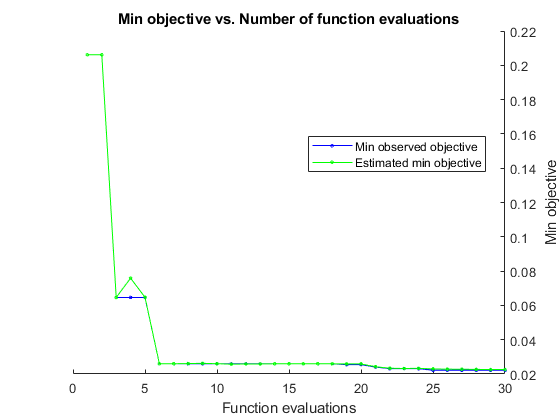

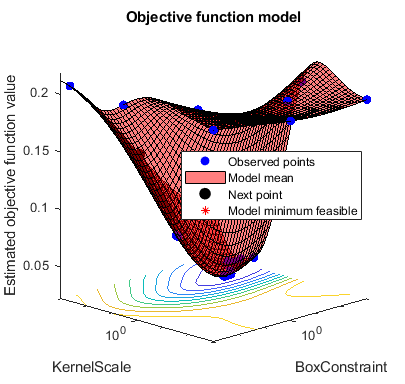


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 62.4388 seconds.
Total objective function evaluation time: 25.8999

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       86.072          23.218   

Observed objective function value = 0.02217
Estimated objective function value = 0.02269
Function evaluation time = 0.48094

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       65.579          23.622   

Estimated objective function value = 0.022602
Estimated function evaluation time = 0.50504



testPr = 0.30;
trainsPr = round(sizes(1)*(1-testPr));

Xtrain = x(1:trainsPr,:);
Ytrain = y(1:trainsPr,:);

Xtest = x(trainsPr + 1 : sizes(1), :);
Ytest = y(trainsPr + 1 : sizes(1), :);

model = fitcsvm(Xtrain,Ytrain, 'KernelFunction','rbf','OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'));

result = predict(model, Xtest);
acuracy = sum(result == Ytest)/length(Ytest) * 100;
disp(acuracy);

   97.4697



#### Treinando o modelo

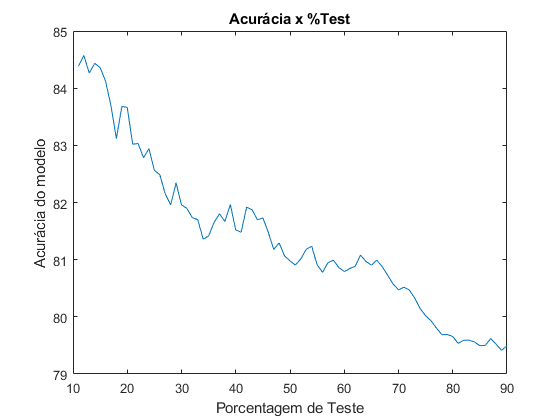

trainRg = (1:1:80);
acuracy = trainRg;
for i = trainRg
    testPr = (i+10)/100;
    trainsPr = round(sizes(1)*(1-testPr));
    
    Xtrain = x(1:trainsPr,:);
    Ytrain = y(1:trainsPr,:);
    
    Xtest = x(trainsPr + 1 : sizes(1), :);
    Ytest = y(trainsPr + 1 : sizes(1), :);
    
    model = fitcsvm(Xtrain,Ytrain, 'KernelFunction','rbf');
    result = predict(model, Xtest);
    acuracy(i) = sum(result == Ytest)/length(Ytest) * 100;
end
figure(4);
plot(trainRg+10, acuracy);
xlabel("Porcentagem de Teste");
ylabel("Acurácia do modelo");
title("Acurácia x %Test");